%% EE406 Experiment 6 Calculations
clc;
clear all;
close;

set(0,'defaultTextInterpreter','latex')
set(0,'DefaultLineLineWidth',2)
set(0,'defaultAxesFontSize',13)

sympref('MatrixWithSquareBrackets',true)

ans = logical
   1



%% Symbolic definitions 
s=tf('s');

G=1/(s+1)

G =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



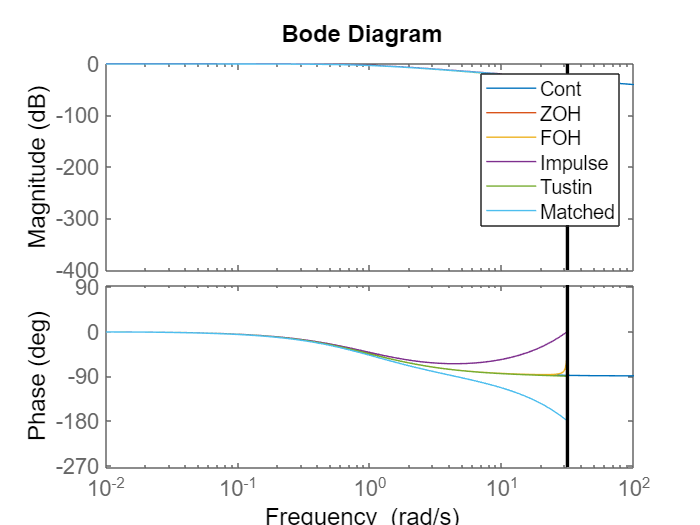

Ts=0.1;
Gz = c2d(G,Ts,'zoh');
Gf = c2d(G,Ts,'foh');
Gi = c2d(G,Ts,'impulse');
Gt = c2d(G,Ts,'tustin');
Gm = c2d(G,Ts,'matched');
bode(G,Gz,Gf,Gi,Gt,Gm)
legend("Cont","ZOH","FOH","Impulse","Tustin","Matched");

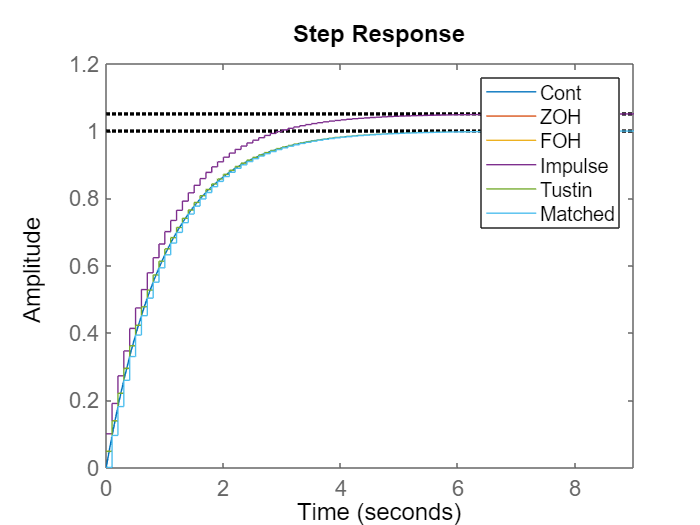

step(G,Gz,Gf,Gi,Gt,Gm)
legend("Cont","ZOH","FOH","Impulse","Tustin","Matched");

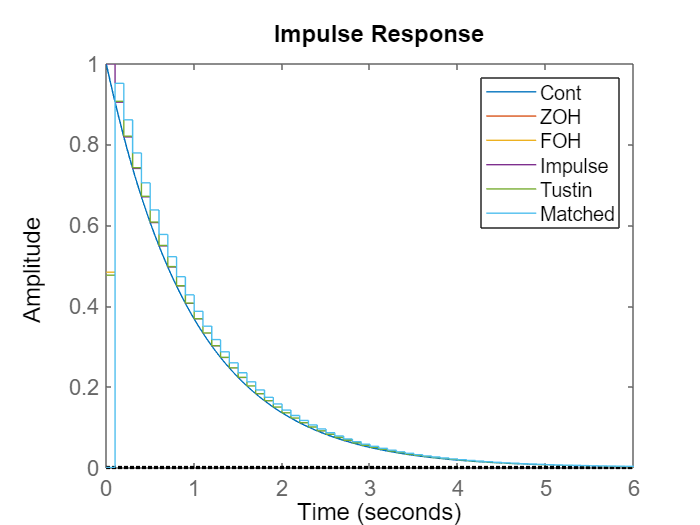

impulse(G,Gz,Gf,Gi,Gt,Gm)
legend("Cont","ZOH","FOH","Impulse","Tustin","Matched");

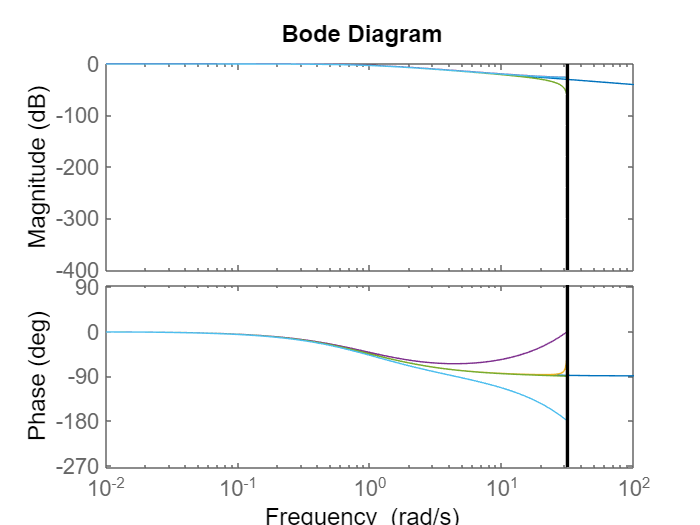

bode(G,Gz,Gf,Gi,Gt,Gm)



s = tf('s');
H = 2.45/(s*(s+17.13));
figure;
bode(H);
hold on
%% T = 0.001
T = 0.001;
Hz = c2d(H,T,'zoh');
bode(Hz);
%% T = 0.01
T = 0.01;
Hz = c2d(H,T,'zoh');
bode(Hz);
%% T = 0.1
T = 0.1;
Hz = c2d(H,T,'zoh');
bode(Hz);
%% T = 1
T = 1;
Hz = c2d(H,T,'zoh');
bode(Hz);
legend('T = 0.001','T = 0.01','T = 0.1','T = 1');
set(gcf,'Position',[0 0 1200 600]);
set(0,'defaultTextInterpreter','latex')
title("\bf{Zero Order Hold Transformation for Different Sampling Rates}",'FontSize',14);
set(0,'DefaultLineLineWidth',0.6)
set(0,'defaultAxesFontSize',12)
grid on



%% Tustin, Bilinear, Trapezoidal
figure;
bode(H);
hold on
%% T = 0.001
T = 0.001;
Hz = c2d(H,T,'tustin');
bode(Hz);
%% T = 0.01
T = 0.01;
Hz = c2d(H,T,'tustin');
bode(Hz);
%% T = 0.1
T = 0.1;
Hz = c2d(H,T,'tustin');
bode(Hz);
%% T = 1
T = 1;
Hz = c2d(H,T,'tustin');
bode(Hz);
title('Tustin transformation')
legend('T = 0.001','T = 0.01','T = 0.1','T = 1');
%% Pole zero matching
figure;
bode(H);
hold on
%% T = 0.001
T = 0.001;
Hz = c2d(H,T,'matched');
bode(Hz);
%% T = 0.01
T = 0.01;
Hz = c2d(H,T,'matched');
bode(Hz);
%% T = 0.1
T = 0.1;
Hz = c2d(H,T,'matched');
bode(Hz);
%% T = 1
T = 1;
Hz = c2d(H,T,'matched');
bode(Hz);

title('Pole zero matching transformation')
legend('T = 0.001','T = 0.01','T = 0.1','T = 1');



s = tf('s');
z = tf('z');
H = 2.45/(s*(s+17.13));

for T = [1/100 1/25]
    G_z = c2d(H,T,'zoh');
    [num, den]=tfdata(G_z);
    den=cell2mat(den);
    num=cell2mat(num);
    A= den;
    B= num;
    Gc_z1=tf(A,B,T);
    Gc_z2=tf(1,[1 -1],T);
    Gc_z=Gc_z1*Gc_z2
end

Gc_z =
 
          z^2 - 1.843 z + 0.8426
  ---------------------------------------
  0.0001158 z^2 - 6.425e-06 z - 0.0001094
 
Sample time: 0.01 seconds
Discrete-time transfer function.


Gc_z =
 
         z^2 - 1.504 z + 0.504
  ------------------------------------
  0.00158 z^2 - 0.0003216 z - 0.001258
 
Sample time: 0.04 seconds
Discrete-time transfer function.



% 
% xc_ddot = (-(Ip+Mp*lp^2)*Beq*(xc_dot)+(Mp^2*lp^3+Ip*Mp*lp)*sin(alpha)*alpha_dot^2 ...
%     +(Ip+Mp*lp^2)*(-(Eff_g*Kg^2*Eff_m*Kt*Km*xc_dot)/(Rm*r_mp^2)+(Eff_g*Kg*Eff_m*Kt*Vm)/(Rm*r_mp)) ...
%     +Mp*lp*cos(alpha)*Bp*alpha_dot+Mp^2*lp^2*g*cos(alpha)*sin(alpha))/((Mc+Mp)*Ip+Mc*Mp*lp^2+Mp^2*lp^2*sin(alpha)^2);
% 
% alpha_ddot = (-(Mc+Mp)*Mp*g*lp*sin(alpha)-(Mc+Mp)*Bp*alpha_dot ...
%     -(-(Eff_g*Kg^2*Eff_m*Kt*Km*xc_dot)/(Rm*r_mp^2)+(Eff_g*Kg*Eff_m*Kt*Vm)/(Rm*r_mp))*Mp*lp*cos(alpha) ...
%     -Mp^2*lp^2*sin(alpha)*cos(alpha)*alpha_dot^2+Mp*lp*cos(alpha)*Beq*xc_dot)/((Mc+Mp)*Ip+Mc*Mp*lp^2+Mp^2*lp^2*sin(alpha)^2);


% %%
% Lp = ( 25 + 1 / 4 ) * 0.0254;  % = 0.6413;
% lp = 13 * 0.0254;  % = 0.3302
% Jeq = Mc + Eff_g * Kg^2 * Jm / r_mp^2;
% Jp = Mp * Lp^2 / 12;  % = 7.8838 e-3
% Jt = (Jeq + Mp)*Jp + Jeq*Mp*lp^2;
% A = [0 0 1 0;
%      0 0 0 1;
%      0 Mp^2*lp^2*g/Jt -Beq*(Jp+Mp*lp^2)/Jt -Mp*lp*Bp/Jt;
%      0 Mp*g*lp*(Jeq+Mp)/Jt -Beq*Mp*lp/Jt -Bp*(Jeq+Mp)/Jt];
% 
% B = [0; 0; (Jp+Mp*lp^2)/Jt; Mp*lp/Jt];
% C = eye(2,4);
% D = zeros(2,1);
% 
% A(3,3) = A(3,3) - B(3)*Eff_g*Kg^2*Eff_m*Kt*Km/r_mp^2/Rm;
% A(4,3) = A(4,3) - B(4)*Eff_g*Kg^2*Eff_m*Kt*Km/r_mp^2/Rm;
% B = Eff_g*Kg*Eff_m*Kt/r_mp/Rm*B;
%%
% Evaluate Jacobian
A = jacobian([xc_dot,alpha_dot,xc_ddot,alpha_ddot],[xc; alpha; xc_dot; alpha_dot]);
B = jacobian([xc_dot,alpha_dot,xc_ddot,alpha_ddot],[Vm]);
% Equilibrium point [0 0 0 0]
xc=0;
xc_dot = 0;
alpha = 0;
alpha_dot = 0;
Vm=0;

A = double(subs(A))

A =          0         0    1.0000         0
         0         0         0    1.0000
         0    2.2646  -15.8597   -0.0073
         0   27.8243  -36.5467   -0.0896


sym(A)

$$ans = \left[\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & 2.2646 & -15.8597 & -0.0073\\ 0 & 27.8243 & -36.5467 & -0.0896 \end{array}\right]$$

B = double(subs(B))

B =          0
         0
    2.2734
    5.2389


C = [1 0 0 0 ; 0 1 0 0];
D = [0;0];

%% SS2TF
[num,den] = ss2tf(A,B,[1 0 0 0],[0]);
xc_tf = tf(num,den)

xc_tf =
 
      2.273 s^2 + 0.1655 s - 51.39
  -------------------------------------
  s^4 + 15.95 s^3 - 26.67 s^2 - 358.5 s
 
Continuous-time transfer function.



   [num,den] = tfdata(xc_tf);
   syms s;
   t_sym = poly2sym(cell2mat(num),s)/poly2sym(cell2mat(den),s);
   sym(t_sym)

$$ans = -\frac{2.2734\,s^{2}+0.1655\,s-51.3918}{-s^{4}-15.9493\,s^{3}+26.6701\,s^{2}+358.5214\,s}$$



[num,den] = ss2tf(A,B,[0 1 0 0],[0]);
alpha_tf = tf(num,den)

alpha_tf =
 
   5.239 s^2 + 0.002115 s - 4.283e-15
  -------------------------------------
  s^4 + 15.95 s^3 - 26.67 s^2 - 358.5 s
 
Continuous-time transfer function.



[num,den] = tfdata(alpha_tf);
syms s;
t_sym = poly2sym(cell2mat(num),s)/poly2sym(cell2mat(den),s);
sym(t_sym)

$$ans = -\frac{5.2389\,s^{2}+0.0021\,s-4.2833e-15}{-s^{4}-15.9493\,s^{3}+26.6701\,s^{2}+358.5214\,s}$$

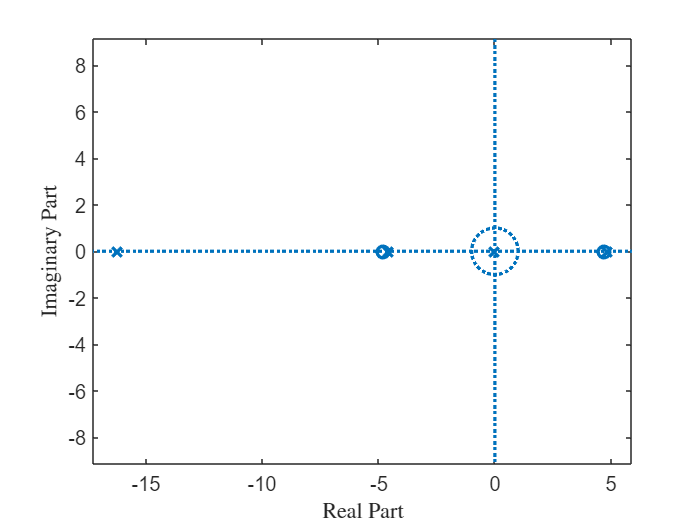

[z,p,k] = ss2zp(A,B,[1 0 0 0],[0]);
sys = ss(A,B,[1 0 0 0],[0]);
grid minor
zplane(z,p)

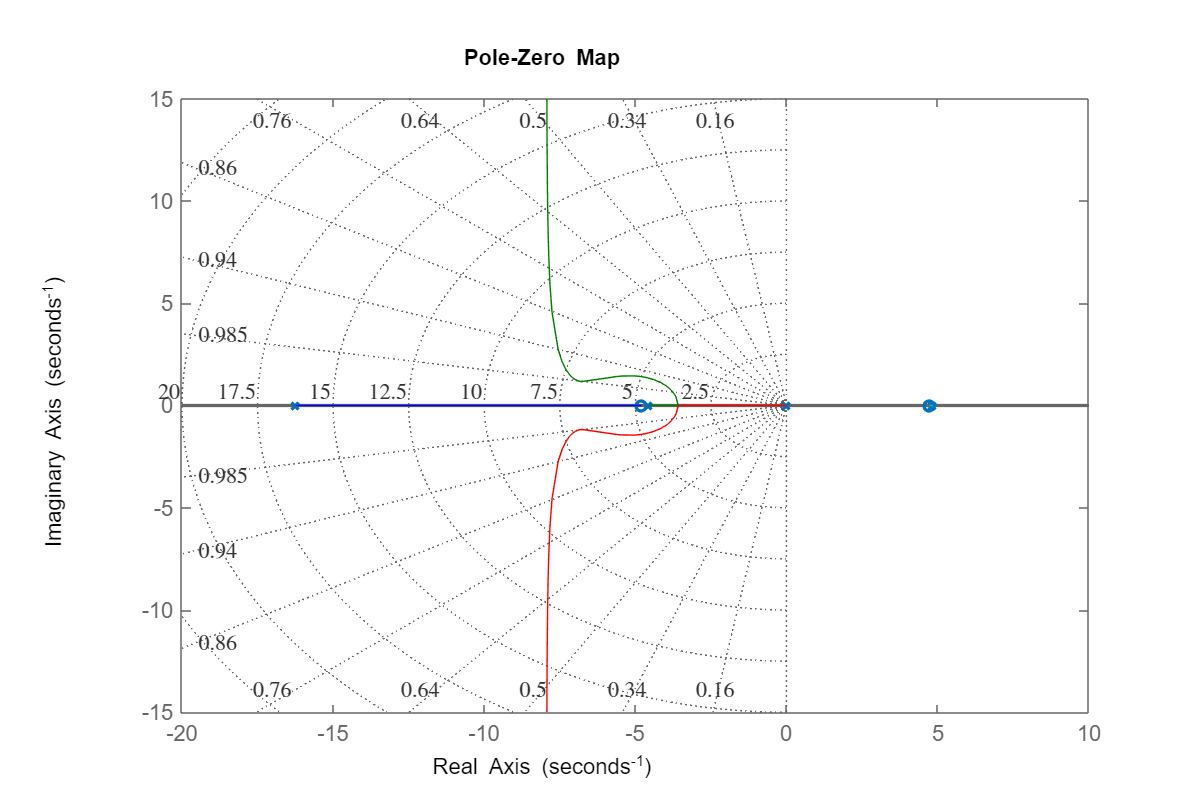



figure;
rlocus(sys);
title("\bf{Pole-Zero Map}",'FontSize',14);
set(gcf,'Position',[0 0 1200 800]);
set(0,'defaultTextInterpreter','latex')
set(0,'DefaultLineLineWidth',0.6)
set(0,'defaultAxesFontSize',12)
grid on

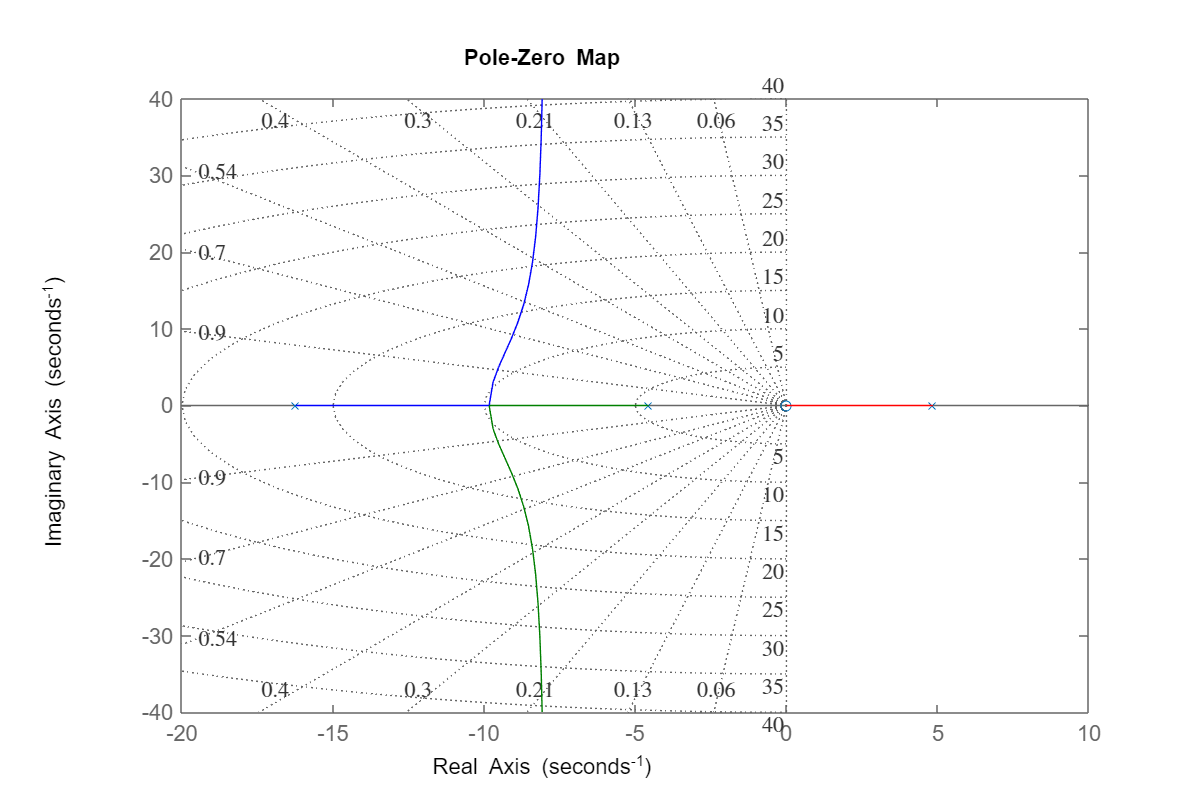

sys = ss(A,B,[0 1 0 0],[0]);

figure;
rlocus(sys);
title("\bf{Pole-Zero Map}",'FontSize',14);
set(gcf,'Position',[0 0 1200 800]);
set(0,'defaultTextInterpreter','latex')
set(0,'DefaultLineLineWidth',0.6)
set(0,'defaultAxesFontSize',12)
grid on


Co = ctrb(ss(A,B,C,D))

Co = 	1.0e+04 *

         0    0.0002   -0.0036    0.0585
         0    0.0005   -0.0084    0.1472
    0.0002   -0.0036    0.0585   -0.9476
    0.0005   -0.0084    0.1472   -2.3833


det(Co)

ans = -7.2488e+04

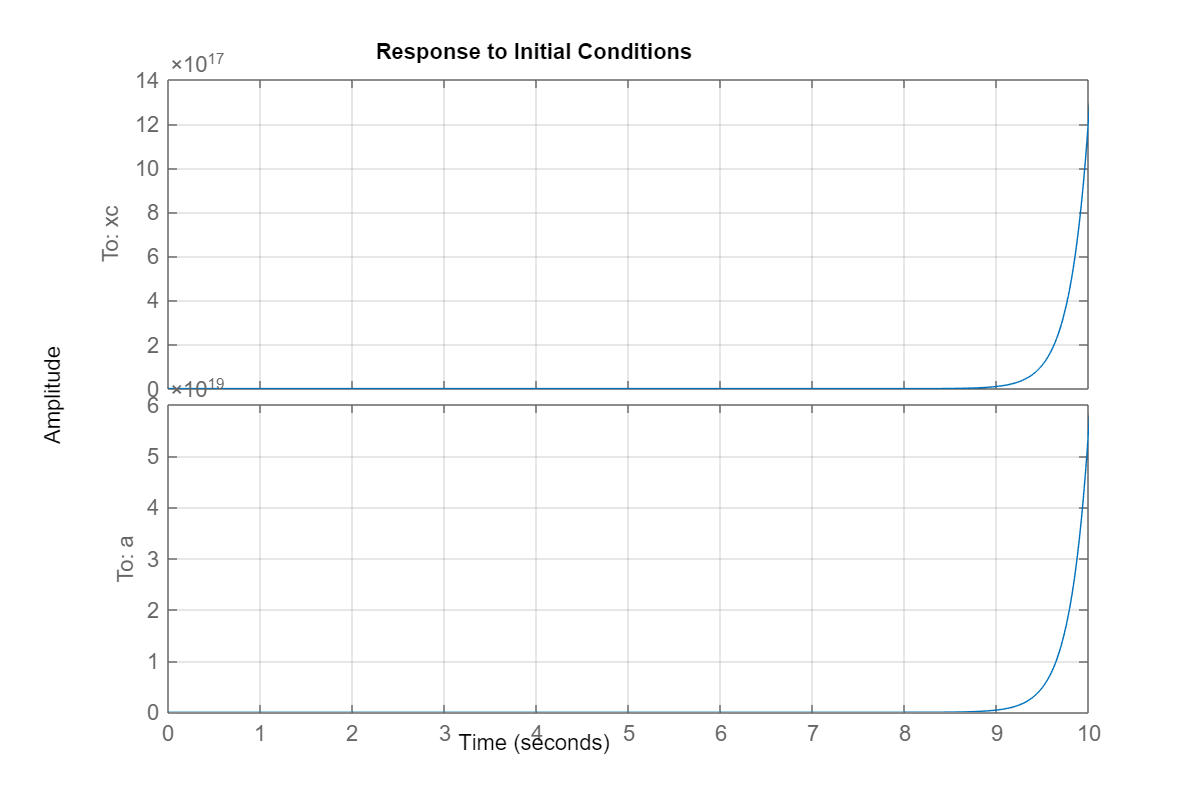


sys = ss (A, B, C, D, 'statename', {'xc' 'a' 'xc_dot' 'a_dot'}, ...
'inputname', 'Vm', ...
'outputname', {'xc' 'a'});
x0 =[0; 10e-2; 0; 0];
initial(sys,x0)
xlim([0 10]);
grid on

figure;
set(gcf,'Position',[0 0 1200 800]);
set(0,'defaultTextInterpreter','latex')
set(0,'DefaultLineLineWidth',0.6)
set(0,'defaultAxesFontSize',12)
grid on

tiledlayout(2,1)

nexttile
t = [0:0.01:2*pi]

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


a = 0.05*exp(-0.7.*t).*sin(8*t)-2;
plot(t,a)
xlabel 'Time (s)'
ylabel 'Cart Position (m)'
title('Xc (m) vs Time (s)')
grid on
set(0,'defaultTextInterpreter','tex')
nexttile
t = [0:0.01:2*pi]

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


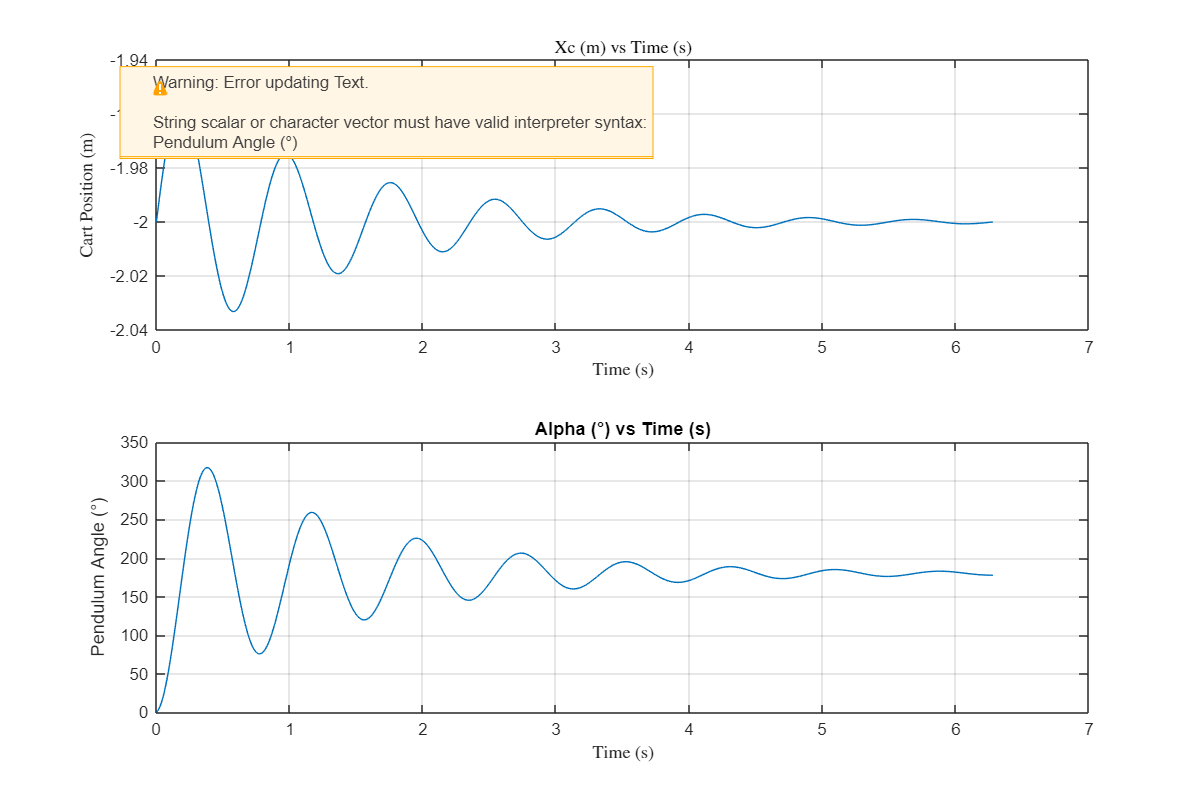

a = -180*exp(-0.7.*t).*cos(8*t)+180;
set(0,'defaultTextInterpreter','latex')
plot(t,a)
xlabel 'Time (s)'
ylabel 'Pendulum Angle (°)'
title('Alpha (°) vs Time (s)')
grid on